# Template of Manipulator Short project: Skull tumor surgery

**List of to do:**

The Robotic environment must contain:

1.- Operating table. It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Use 'patch' or 'fill3' functions to model it.

*Add your comemnts here..... be concise*

clear;
clc;

## put your code Here

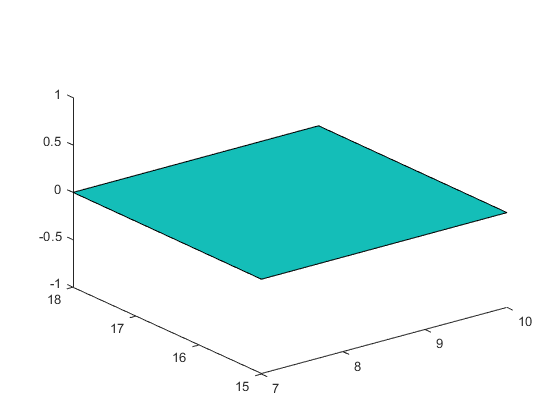

% Crate the tool table 
X = [7 7 10 10];
Y = [18 15 15 18];
Z = [0 0 0 0];
C = [0 0 0 0];
Table = fill3(X,Y,Z,C);

2.- A 3D model of a human body on the operating table. Use the Workspace given, or other you might find.

*Add your comemnts here..... be concise*

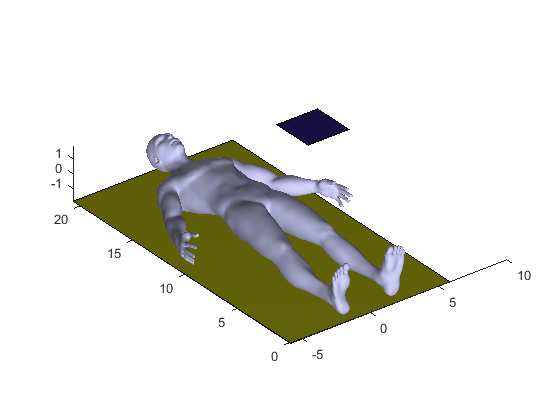

%% put your code Here
HumanBody = load("Model\F_V_Human_Body.mat");
patch('Faces', HumanBody.F, 'Vertices', HumanBody.V,...
      'FaceColor',[0.8 0.8 1.0],...
      'EdgeColor','none',...
      'FaceLighting',    'gouraud',     ...
      'AmbientStrength', 0.8,'FaceAlpha', 0.8);
camlight('headlight');
material('dull');
axis equal
hold on;
% Find the bounding box of the human body to create the operating table 
xmax = max(HumanBody.V(:, 1));
xmin = min(HumanBody.V(:, 1));
ymax = max(HumanBody.V(:, 2));
ymin = min(HumanBody.V(:, 2));
zmax = max(HumanBody.V(:, 3));
zmin = min(HumanBody.V(:, 3));
X = [xmin xmin xmax xmax];
Y = [ymin ymax ymax ymin];
Z = [zmin zmin zmin zmin];
C = [2 2 2 2];
Table = fill3(X,Y,Z,C);

3.- A human skull model, embedded in the head of the human. Place the fiducials.

*Add your comemnts here.....be concise*

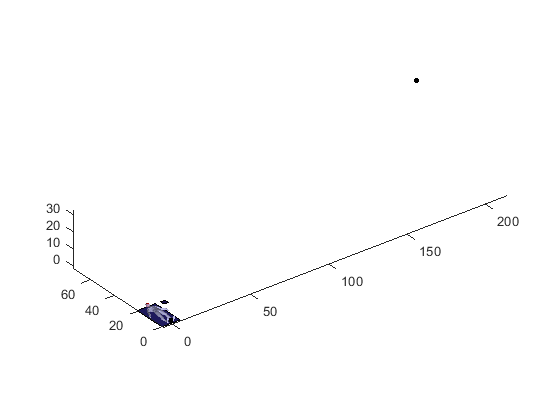

%% put your code Here
Skull = load("Model\F_V_N_Skull.mat");
Vertices = Skull.Ve/12.5; 
Vertices = [Vertices'; ones(1, size(Vertices,1))];
Vertices = transl(0, 18.25, 0)*trotx(-pi/2)*Vertices;
Vertices = Vertices(1:3,:);
Vertices = Vertices';
patch('Faces', Skull.Fa, 'Vertices', Vertices,...
      'FaceColor', 'red' ,...
      'EdgeColor','none');
material('dull');
axis equal

%Fiducials 
[X1 Y1 Z1] = sphere;
surf(X1+213,Y1+73,Z1+32);
[X2 Y2 Z2] = sphere;
surf(X2,Y2,Z2);
[X3 Y3 Z3] = sphere;
surf(X3,Y3,Z3);

4.- Use the Dicom images to get the points of the outer perimeter of the tumor relative to some reference frame located in the human skull.

*Add your comemnts here.....be concise*

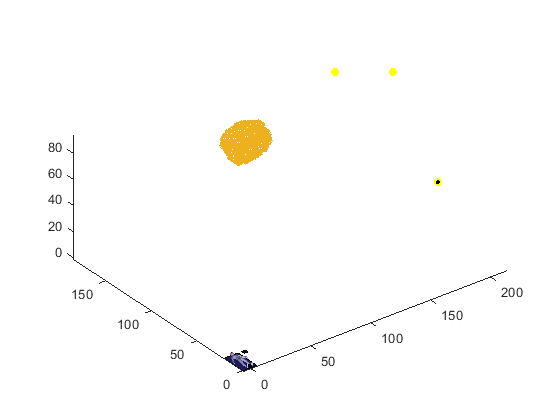

% put your code Here
points = int64.empty(0,3);
%figure;
for i = 65:89
    path = cat(2,['DICOM\IMG00'], num2str(i),['.dcm']);
    I = dicomread(path);
    %imshow(I, [])
    BW = imbinarize(mat2gray(I),'adaptive');
    %imshow(BW, [])
    %imshow(filtered, [])
    R = regionprops(BW, 'PixelList','PixelIdxList');
    for j = 1:size(R)
        if ~ismember([129,95],R(j).PixelList,'rows')
            BW(R(j).PixelIdxList) = 0;
        end
    end
    %imshow(filtered)
    se = strel('disk', 3);
    filtered = imopen(BW, se);
    filtered = bwareafilt(filtered,1);
    filtered = imfill(filtered,'holes');
    se = strel('disk', 5);
    filtered = imclose(filtered, se);
    perimetre = bwperim(filtered);
    %imshow(perimetre);
    %imshow(imoverlay(mat2gray(I),perimetre,'yellow'));
    %drawnow;
    %pause(0.1)
    R = regionprops(filtered,'PixelList');
    for j = 1:size(R.PixelList)
        points = [points; [R.PixelList(j,1) R.PixelList(j,2) i]];
    end
    %points = [points; 
end
fiducials = [213 73 32; 213 185 65; 213 122 94];
scatter3(points(:,2),points(:,1),points(:,3),1) 
hold on
scatter3(fiducials(:,1),fiducials(:,2),fiducials(:,3), 'y', 'filled') 
hold off
axis equal
axis tight

*First approach:**  Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

5.- Display all necessary Reference Frames

*Add your comemnts here.....be concise*

%% put your code Here

6.- Place the 6R Robot manipulator nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560.

*Add your comemnts here.....be concise*

%% put your code Here

7.- Get the transformation that maps tumor points in Robot Frame.

*Add your comemnts here.....be concise*

%% put your code Here

8.- Print the tumor points in Robot Frame.

*Add your comemnts here.....be concise*

%% put your code Here

9.- Prepare a script that perform a biopsy. Zoom in the scene

*Add your comemnts here.....be concise*

%% put your code Here

10.- Prepare a script that perform trepanation.

*Add your comemnts here.....be concise*

%% put your code Here

11.- Prepare a script that perform tumor burning with the laser.

*Add your comemnts here.....be concise*

%% put your code Here

12.-Modify your code  to repeat point from 7 till 11 if ZX plane of the Robot is not aligned with the plane of symmetry of the human body. There is a free rotation among these two planes. 

*See: * *‘Sckeching_Key_ideas_students.mlx’ and ‘Triangles_2.mlx’ for inspiration.*

*Add your comemnts here.....be concise*

%% put your code Here